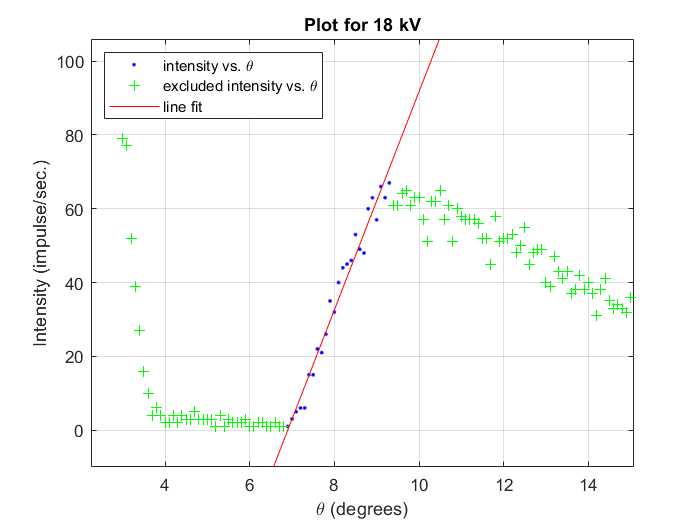

[xData, yData] = prepareCurveData( theta18kV, R18kV );

% Set up fittype and options.
ft = fittype( 'poly1' );
excludedPoints = excludedata( xData, yData, 'Indices', [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 80 81 82 83 84 85 86 87 88 89 90 91 92 93 94 95 96 97 98 99 100 101 102 103 104 105 106 107 108 109 110 111 112 113 114 115 116 117 118 119 120 121 122 123 124 125 126 127 128 129 130 131 132 133 134 135 136 137 138 139 140 141 142 143 144 145 146 147 148 149 150 151 152 153 154 155 156 157 158 159 160 161 162 163 164 165 166 167 168 169 170 171] );
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData, excludedPoints );
legend( h, 'R18kV vs. theta18kV', 'Excluded R18kV vs. theta18kV', 'untitled fit 1', 'Location', 'NorthEast' );
% Label axes
xlabel theta18kV
ylabel R18kV
grid on

xlim([2.25 15.08])
ylim([-10 106])
legend({'intensity vs. \theta','excluded intensity vs. \theta','line fit'},'Location','northwest')
title('Plot for 18 kV')
xlabel('\theta (degrees)')
ylabel('Intensity (impulse/sec.)')


%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients (with 95% confidence bounds):
 %      p1 =       29.58  (27.45, 31.7)     \pm1.06
  %     p2 =      -204.1  (-221.3, -186.8)  \pm8.6

%Goodness of fit:
 % SSE: 315.9
  %R-square: 0.973
  %Adjusted R-square: 0.9718
  %RMSE: 3.706

  % \theta_m=6.900 \pm 0.382